function ystar=cubic_spline(x,y,xstar)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Andrew Hutsell
% MATH 515
% Guided Lab 3


% Please copy this code into a new file and rename cublic_spline.m
% Change the function name in line 1 also to cubic_spline.

% Questions 1-3 ask you to sequentially add to the template to create a
% cubic spline interpolator. Much of the info is given to you but you will
% need to think beyond "cut and paste".
% Question 4 asks you to interpet code already given.
% Questions 5-6 ask you to run your interpolator with two different sets of
% data. You may want to create a script that includes both data sets, from
% which you run cubic_spline.m.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% Question 1

% n relative to # of data points
n=length(x)-1;

%Initialize A and rvec (the RHS)
A=zeros(n+1,n+1);
rvec=zeros(n+1,1);

%Calculate vector of h values (not necessarily equally spaced)
h = diff(x);
a = y;
%Populate upper left and lower right of A
A(1,1)=1;
A(n+1,n+1)=1;

%Populate rest of matrix A and answer vector r
for i=2:n
    A(i,i-1)= h(i-1);
    A(i,i)= 2 * (h(i-1)+h(i));
    A(i,i+1)= h(i);
    rvec(i) = 3 * ((a(i+1) - a(i)) / h(i) ...
        - (a(i) - a(i-1)) / h(i-1) );
end

%%% Question 2

c = A\rvec

%%% Question 3

%(a)
for j=1:n+1
    a(j) = y(j);
end

%(b-c)
for j = 1:n
    d(j) = (c(j+1) - c(j)) / (3*h(j));

    b(j) = (a(j+1) - a(j))/h(j) - (1/3)*(2*c(j) + c(j+1))*h(j);
end

%%% At this point you have calculated all values for a,b,c,d

%%% Question 4
% You do not need to add code -- the question asks you to determine
% what is happening in the existing code given to you here.

coeffs=[];
for k=1:n
    coeffs(k,:)=[d(k) c(k) b(k) a(k)];
end

breaks=[x]
pp=mkpp(breaks,coeffs)
ystar=ppval(pp,xstar)

%%% Question 5-6
% You do not need to add code here -- the questions ask you to interpolate
% two different sets of data and evaluate at two xstar values, one with a known output 
% for ystar to check your code. 
end

% Molality
x = [0.005 0.010 0.02 0.05 0.1 0.2 0.5 1 2];
y = [0.924 0.896 0.859 0.794 0.732 0.656 0.536 0.430 0.316];

xstar = 0.032;

cubic_spline(x,y,xstar)

c =          0
  179.6586
   31.0243
   10.7157
    2.6951
    0.9567
    0.1503
    0.0729
         0


breaks =     0.0050    0.0100    0.0200    0.0500    0.1000    0.2000    0.5000    1.0000    2.0000


pp = struct with fields:
      form: 'pp'
    breaks: [0.0050 0.0100 0.0200 0.0500 0.1000 0.2000 0.5000 1 2]
     coefs: [8×4 double]
    pieces: 8
     order: 4
       dim: 1


ystar = 0.8283

ans = 0.8283



%%% Question 6

% Part a
days_post_birth = [0 6 10 13 17 20 28];
young_leaves = [7 18 45 40 32 30.5 30];
mature_leaves = [7 16 19 15 12 10.5 10];

% This is how the mean weight is estimated at 3 days
xstar = 3;

% In the problem statement, it is not specified which leaves data set to
% use, I will be computing both

young = cubic_spline(days_post_birth,young_leaves,xstar)

c =     0.0000
    1.1803
   -2.2138
    0.3408
    0.2176
    0.0300
         0


breaks =      0     6    10    13    17    20    28


pp = struct with fields:
      form: 'pp'
    breaks: [0 6 10 13 17 20 28]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 7.1888

young = 7.1888

young_spline = spline(days_post_birth,young_leaves,xstar)

young_spline = -2.7094

mature = cubic_spline(days_post_birth,mature_leaves,xstar)

c =     0.0000
   -0.0138
   -0.4937
    0.2389
   -0.0283
    0.0635
         0


breaks =      0     6    10    13    17    20    28


pp = struct with fields:
      form: 'pp'
    breaks: [0 6 10 13 17 20 28]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 11.5619

mature = 11.5619

mature_spline = spline(days_post_birth,mature_leaves,xstar)

mature_spline = 10.4508



% Part b
days = linspace(0,28,1000);
weights_young = cubic_spline(days_post_birth,young_leaves,days);

c =     0.0000
    1.1803
   -2.2138
    0.3408
    0.2176
    0.0300
         0


breaks =      0     6    10    13    17    20    28


pp = struct with fields:
      form: 'pp'
    breaks: [0 6 10 13 17 20 28]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar =     7.0000    6.9852    6.9705    6.9557    6.9410    6.9263    6.9117    6.8971    6.8825    6.8681    6.8537    6.8394    6.8252    6.8111    6.7971    6.7832    6.7695    6.7559    6.7424    6.7292    6.7160    6.7031    6.6903    6.6777    6.6653    6.6532    6.6412    6.6295    6.6180    6.6067    6.5957    6.5849    6.5745    6.5643    6.5544    6.5447    6.5354    6.5264    6.5177    6.5094    6.5014    6.4937    6.4864    6.4794    6.4728    6.4666    6.4608    6.4554    6.4504    6.4458


[weight_young_max, idx] = max(weights_young)

weight_young_max = 45.7172

idx = 380

days_young_max = days(idx)

days_young_max = 10.6226



plot(days, weights_young, 'DisplayName','From Young Leaves')
xlabel('Days')
ylabel('Average Mean Weight (mg)')


hold on
weights_mature = cubic_spline(days_post_birth,mature_leaves,days);

c =     0.0000
   -0.0138
   -0.4937
    0.2389
   -0.0283
    0.0635
         0


breaks =      0     6    10    13    17    20    28


pp = struct with fields:
      form: 'pp'
    breaks: [0 6 10 13 17 20 28]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar =     7.0000    7.0428    7.0856    7.1284    7.1713    7.2141    7.2569    7.2997    7.3425    7.3853    7.4281    7.4709    7.5137    7.5565    7.5993    7.6421    7.6849    7.7277    7.7705    7.8133    7.8561    7.8989    7.9417    7.9845    8.0273    8.0701    8.1129    8.1556    8.1984    8.2412    8.2840    8.3267    8.3695    8.4122    8.4550    8.4978    8.5405    8.5832    8.6260    8.6687    8.7115    8.7542    8.7969    8.8396    8.8824    8.9251    8.9678    9.0105    9.0532    9.0959


[weight_mature_max, idx] = max(weights_mature)

weight_mature_max = 19.1826

idx = 335

days_mature_max = days(idx)

days_mature_max = 9.3614


plot(days, weights_mature, 'DisplayName','From Mature Leaves')
xlabel('Days')
ylabel('Average Mean Weight (mg)')
legend()



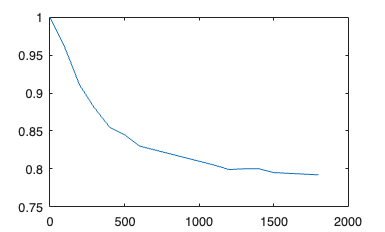

clear;clc; close all;
%%% Question 7
% Data of Dissolved Oxygen Concentration over time from MSETF-TRITIUM
NDOC = [1,0.96,0.91,0.88,0.855,0.845,0.83,0.825,0.82,0.815,0.81,0.805,0.799,0.8,0.8,0.795,0.794,0.793,0.792];
time = [0,100,200,300,400,500,600,700,800,900,1000,1100,1200,1300,1400,1500,1600,1700,1800];


t_interp = linspace(0,1800,100);

NDOC_interp = zeros(size(t_interp));

% Cubic Spline loop
for k = 1:length(t_interp)
    NDOC_interp(k) = cubic_spline(time, NDOC, t_interp(k));
end

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 1

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9934

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9868

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9798

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9723

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9643

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9555

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9461

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9365

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9270

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9181

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9100

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.9031

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8972

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8919

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8871

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8824

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8775

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8725

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8674

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8627

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8585

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8550

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8524

c = 1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8505

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8490

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8476

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8460

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8438

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8412

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8382

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8352

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8324

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8300

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8283

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8271

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8263

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8258

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8253

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8247

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8239

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8230

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8220

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8210

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8200

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8190

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8181

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8172

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8163

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8155

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8145

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8136

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8127

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8118

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8109

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8100

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8092

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8084

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8075

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8066

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8056

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8044

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8031

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8018

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8007

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7997

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7990

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7987

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7987

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7990

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7993

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7998

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8002

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8005

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8007

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8007

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8005

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.8000

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7992

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7983

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7973

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7962

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7954

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7947

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7943

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7941

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7940

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7940

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7940

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7939

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7938

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7936

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7933

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7931

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7929

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7927

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7925

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7923

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7922

c = 19×1
1.0e-05 *

   -0.0000
   -0.1232
    0.1929
   -0.0482
    0.1500
   -0.1019
    0.1077
   -0.0290
    0.0082
   -0.0038
    0.0071
   -0.0247
    0.0615
   -0.0114
   -0.0457


breaks = 1×19
           0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
     coefs: [18×4 double]
    pieces: 18
     order: 4
       dim: 1


ystar = 0.7920

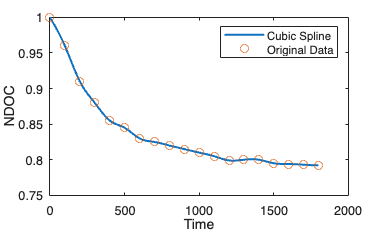


% Plot curve
plot(t_interp, NDOC_interp, 'LineWidth',1.5)
hold on

% Plot original data points (circles only)
plot(time, NDOC, 'o', 'MarkerSize',6)

xlabel('Time')
ylabel('NDOC')
legend('Cubic Spline','Original Data')

clear;clc;close all;
%%% Question 8

NDOC = [1,0.96,0.91,0.88,0.855,0.845,0.83,0.825,0.82,0.815,0.81,0.805,0.799,0.8,0.8,0.795,0.794,0.793,0.792];
time = [0,100,200,300,400,500,600,700,800,900,1000,1100,1200,1300,1400,1500,1600,1700,1800];

% Every Other Point
time_half = time(1:2:end);
NDOC_half = NDOC(1:2:end);

% Every Third Point
time_third = time(1:3:end);
NDOC_third = NDOC(1:3:end);

t_interp = linspace(0,1800,400);

NDOC_half_interp = zeros(size(t_interp));
NDOC_third_interp = zeros(size(t_interp));

for k = 1:length(t_interp)
    NDOC_half_interp(k)  = cubic_spline(time_half,  NDOC_half,  t_interp(k));
    NDOC_third_interp(k) = cubic_spline(time_third, NDOC_third, t_interp(k));
end

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 1

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 1

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9978

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9980

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9956

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9959

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9934

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9939

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9912

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9918

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9890

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9898

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9868

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9877

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9846

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9857

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9824

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9836

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9803

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9816

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9781

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9796

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9759

c = 1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks =            0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9775

c = 1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks =            0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9738

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9755

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9716

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9735

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9694

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9715

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9673

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9695

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9652

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9675

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9630

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9655

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9609

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9635

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9588

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9615

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9567

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9595

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9546

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9575

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9525

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9555

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9505

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9536

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9484

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9516

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9464

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9497

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9443

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9477

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9423

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9458

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9403

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9439

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9383

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9420

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9363

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9401

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9344

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9382

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9324

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9363

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9305

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9344

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9286

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9325

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9267

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9307

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9248

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9289

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9230

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9270

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9212

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9252

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9193

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9234

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9175

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9216

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9158

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9198

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9140

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9181

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9123

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9163

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9106

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9146

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9089

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9129

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9072

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9112

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9056

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9095

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9040

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9078

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9024

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9061

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.9008

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9045

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8992

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9029

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8977

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.9013

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8962

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8997

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8947

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8981

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8932

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8965

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8918

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8950

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8904

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8935

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8889

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8920

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8876

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8905

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8862

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8890

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8849

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8876

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8835

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8861

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8822

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8847

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8809

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8834

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8797

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8820

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8784

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8807

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8772

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8793

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8760

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8780

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8748

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8768

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8736

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8755

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8725

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8743

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8714

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8731

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8702

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8719

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8691

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8707

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8681

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8696

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8670

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8684

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8660

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8673

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8649

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8662

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8639

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8652

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8629

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8641

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8620

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8631

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8610

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8621

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8600

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8611

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8591

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8601

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8582

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8591

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8573

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8582

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8564

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8573

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8556

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8564

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8547

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8555

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8539

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8546

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8531

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8537

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8523

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8529

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8515

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8521

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8507

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8513

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8499

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8505

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8492

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8497

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8485

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8489

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8477

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8482

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8470

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8475

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8463

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8468

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8457

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8461

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8450

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8454

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8443

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8447

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8437

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8440

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8431

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8434

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8425

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8428

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8419

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8421

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8413

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8415

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8407

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8410

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8401

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8404

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8396

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8398

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8390

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8392

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8385

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8387

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8380

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8382

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8375

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8377

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8370

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8371

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8365

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8366

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8360

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8362

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8355

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8357

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8351

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8352

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8346

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8348

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8342

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8343

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8338

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8339

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8334

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8335

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8329

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8330

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8325

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8326

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8322

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8322

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8318

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8318

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8314

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8315

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8310

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8311

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8307

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8307

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8303

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8304

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8300

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8300

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8297

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8297

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8293

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8293

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8290

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8290

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8287

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8287

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8284

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8283

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8281

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8280

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8278

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8277

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8276

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8274

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8273

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8271

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8270

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8269

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8268

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8266

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8265

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8263

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8262

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8260

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8260

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8258

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8258

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8255

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8255

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8252

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8253

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8250

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8251

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8248

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8248

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8245

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8246

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8243

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8244

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8240

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8242

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8238

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8240

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8236

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8238

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8234

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8236

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8231

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8234

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8229

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8232

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8227

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8230

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8225

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8228

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8223

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8226

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8221

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8224

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8219

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8222

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8217

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8221

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8215

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8219

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8213

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8217

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8211

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8215

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8209

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8213

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8207

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8211

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8205

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8210

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8203

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8208

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8202

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8206

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8200

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8204

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8198

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8202

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8196

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8201

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8194

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8199

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8192

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8197

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8190

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8195

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8189

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8193

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8187

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8191

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8185

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8189

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8183

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8188

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8181

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8186

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8179

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8184

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8177

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8182

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8176

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8180

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8174

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8178

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8172

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8176

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8170

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8174

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8168

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8172

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8166

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8170

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8164

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8168

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


ystar = 0.8162

c = 10×1
1.0e-06 *

    0.0000
    0.5630
    0.3731
    0.1946
   -0.0264
   -0.0891
    0.3078
   -0.2421
    0.1355
         0


breaks = 1×10
           0         200         400         600         800        1000        1200        1400        1600        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 200 400 600 800 1000 1200 1400 1600 1800]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


ystar = 0.8165

c = 7×1
1.0e-06 *

    0.0000
    0.5388
    0.1781
   -0.0846
    0.1270
   -0.0234
         0


breaks = 1×7
           0         300         600         900        1200        1500        1800


pp = struct with fields:
      form: 'pp'
    breaks: [0 300 600 900 1200 1500 1800]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1




% Plot spline using every other point
plot(t_interp, NDOC_half_interp, 'LineWidth',1.5)
hold on

% Plot spline using every third point
plot(t_interp, NDOC_third_interp, 'LineWidth',1.5)

% Plot original data (circles only)
plot(time, NDOC, 'o', 'MarkerSize',6)

xlabel('Time')
ylabel('NDOC')
legend('Every Other Point','Every Third Point','Original Data')